# SYED MUHAMMAD ZAIN 329876 ASSIGNMENT 1 ML 

## Training Data initialization and plotting

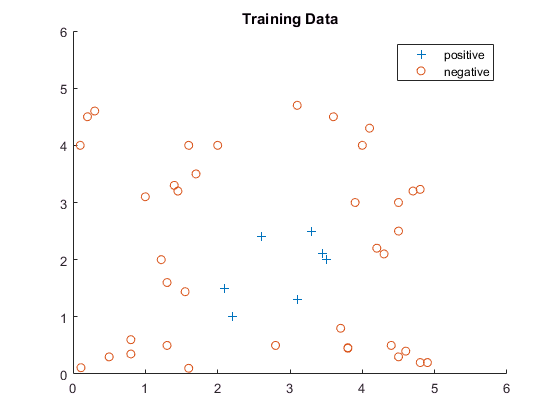

%Training Data x y and x2 y2 for positive and negative points
x=[2.2,2.1,2.6,3.3,3.1,3.5,3.45];
y=[1,1.5,2.4,2.5,1.3,2,2.11];
x2=[0.11,0.5,0.8,0.8,1.3,1.6,2.8,1.7,2,1.6,3.7,3.8,3.8,4.5,4.4,4.8,4.9,4.6,4.3,4.2,3.9,4.5,4.5,4.7,4.8,3.1,3.6,4,4.1,0.1,0.2,0.3,1.55,1.3,1.22,1,1.4,1.45];    
y2=[0.11,0.3,0.35,0.6,0.5,0.1,0.5,3.5,4,4,0.8,0.45,0.46,0.3,0.5,0.2,0.2,0.4,2.1,2.2,3,2.5,3,3.2,3.23,4.7,4.5,4,4.3,4,4.5,4.6,1.44,1.6,2,3.1,3.3,3.2] ;
figure(1)
scatter(x,y,'+')
axis([0 6 0 6])
hold on
scatter(x2,y2)
title('Training Data')
legend('positive','negative')

## Hypothesis Formulation Both Specific and General

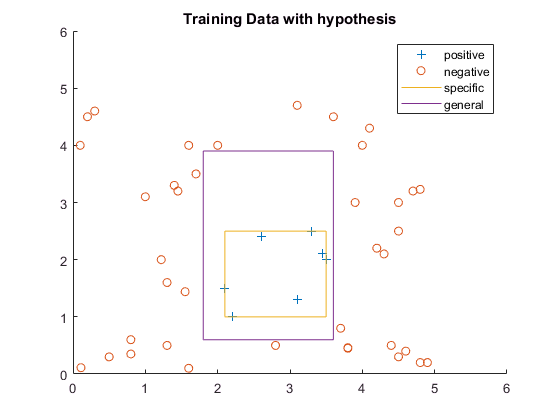

%hypothesis with specific and general
figure(2)
scatter(x,y,'+')
axis([0 6 0 6])
hold on
scatter(x2,y2)
hold on
%calculating specific hypothesis
x3=[min(x),max(x),max(x),min(x),min(x)];
y3=[min(y),min(y),max(y),max(y),min(y)];
plot(x3,y3)
hold on
%calculating general hypothesis
edgex=[2.8,1.7,2,3.7];
edgey=[0.5,3.5,4,0.8];
edgex=edgex-0.1;
edgey=edgey-0.1;
edgey(1)=edgey(1)+0.2;
edgex(2)=edgex(2)+0.2;
x4=[min(edgex),max(edgex),max(edgex),min(edgex),min(edgex)];
y4=[min(edgey),min(edgey),max(edgey),max(edgey),min(edgey)];
plot(x4,y4)
title('Training Data with hypothesis')
legend('positive','negative','specific','general')

## Generating and Plotting test data

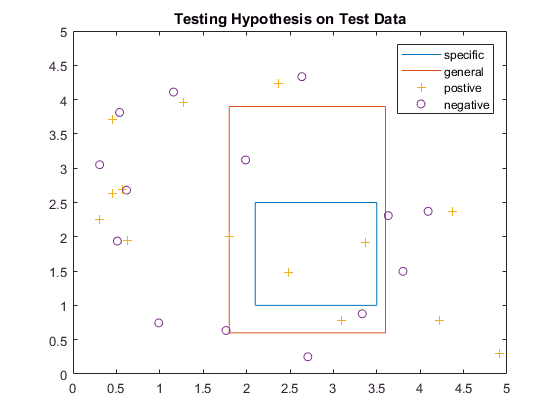

figure(3)
plot(x3,y3)
axis([0 5 0 5])
hold on
plot(x4,y4)
hold on
%testing data
%generate 15 numbers from range (0 ,5)
%for both positive and negative
rng(3,'simdTwister');
rx=0+(5-0).*rand(15,1);
ry=0+(5-0).*rand(15,1);
rx2=0+(5-0).*rand(15,1);
ry2=0+(5-0).*rand(15,1);
scatter(rx,ry,'+')
hold on
scatter(rx2,ry2)
title('Testing Hypothesis on Test Data')
legend('specific','general','postive','negative')

## Checking if the positive point inside and outside hypothesis

% checking if the positive point inside and outside hypothesis
[in1,on1] = inpolygon(rx,ry,x3,y3);
[in2,on2]=inpolygon(rx,ry,x4,y4);
points_in_specific=numel(rx(in1));
points_on_specific=numel(rx(on1));
PTinspecificPositive=points_in_specific+points_on_specific;
points_in_generalPositive=numel(rx(in2));
points_on_generalPositive=numel(rx(on2));
PTingeneralPositive=points_in_generalPositive+points_on_generalPositive;
%calculation of accuracies
TotalpointsP=numel(rx);
PToutsideSPositive=TotalpointsP-PTinspecificPositive;
PToutsideGPositive=TotalpointsP-PTingeneralPositive;
inside_SpecficP=(PTinspecificPositive/TotalpointsP)*100;
outside_SpecificP=(PToutsideSPositive/TotalpointsP)*100;
inside_GeneralP=(PTingeneralPositive/TotalpointsP)*100;
outside_GeneralP=(PToutsideGPositive/TotalpointsP)*100;
PointTablePositive=table(PTinspecificPositive,PToutsideSPositive,PTingeneralPositive,PToutsideGPositive);
accuracytablePositive=table(inside_SpecficP,outside_SpecificP,inside_GeneralP,outside_GeneralP);

## Checking negative points inside and outside Hypothesis 

%points inside and outside rectangle which are negative
[in1,on1] = inpolygon(rx2,ry2,x3,y3);
[in2,on2]=inpolygon(rx2,ry2,x4,y4);
points_in_specific1=numel(rx2(in1));
points_on_specific1=numel(rx2(on1));
PTinspecificNegative=points_in_specific1+points_on_specific1;
points_in_generalNegative=numel(rx2(in2));
points_on_generalNegative=numel(rx2(on2));
PTingeneralNegative=points_in_generalNegative+points_on_generalNegative;
%calculation of accuracies
TotalpointsN=numel(rx2);
PToutsideSNegative=TotalpointsN-PTinspecificNegative;
PToutsideGNegative=TotalpointsN-PTingeneralNegative;
inside_SpecficN=(PTinspecificNegative/TotalpointsN)*100;
outside_SpecificN=(PToutsideSNegative/TotalpointsN)*100;
inside_GeneralN=(PTingeneralNegative/TotalpointsN)*100;
outside_GeneralN=(PToutsideGNegative/TotalpointsN)*100;
PointDistNegative=table(PTinspecificNegative,PToutsideSNegative,PTingeneralNegative,PToutsideGNegative);
AccuracyTableNegative=table(inside_SpecficN,outside_SpecificN,inside_GeneralN,outside_GeneralN);

## Displaying points and accuracies

PointTablePositive

PointTablePositive = 1×4 table
    PTinspecificPositive    PToutsideSPositive    PTingeneralPositive    PToutsideGPositive
    ____________________    __________________    ___________________    __________________

    2                       13                    4                      11                


accuracytablePositive

accuracytablePositive = 1×4 table
    inside_SpecficP    outside_SpecificP    inside_GeneralP    outside_GeneralP
    _______________    _________________    _______________    ________________

    13.333             86.667               26.667             73.333          


PointDistNegative

PointDistNegative = 1×4 table
    PTinspecificNegative    PToutsideSNegative    PTingeneralNegative    PToutsideGNegative
    ____________________    __________________    ___________________    __________________

    0                       15                    2                      13                


AccuracyTableNegative

AccuracyTableNegative = 1×4 table
    inside_SpecficN    outside_SpecificN    inside_GeneralN    outside_GeneralN
    _______________    _________________    _______________    ________________

    0                  100                  13.333             86.667          


# MATLAB CODE EXPLANATION

- For plotting simple scatter plot is used with legend command for all the plots

- Figure is used for separate plots

-  Hold on command is used for overlapping plots

-  Training data is manually entered divided into positive and negative training samples

-  For calculation of specific max and minimum points of the positive training data samples are used to construct specific rectangle

-  For calculation of general max and minimum points of the required edges of the negative training data samples are used to construct general rectangle

-  Rand command is used to general random numbers for test data 15 points from 0 to 5 range are generated for both positive and negative test data samples

-  In polygon command is used for finding the points which are inside and on the rectangle for both specific and general

-  Inpolygon uses the vertices of the rectangles of specific and general as well as the required randomly general points as inputs

-  After finding the points inside subtraction from total gives points outside

-  Inside and outside points are converted to accuracy with the formula required/total x 100